% Οι παράμετροι που χρησιμοποιούνται στις 2 εξισώσεις
params.C = 200;
params.gl = 10;
params.El = -58;
params.vt = -50;
params.delT = 2;
params.a = 2;
params.tauW = 120;
params.b = 100;
params.vreset = -46;
params.w = 0;

params.simDur = 500;
params.dt = 0.01;
params.input = 500;

memvolt = simulateAdEx(params);

    Η simulateAdEx είναι μια συνάρτηση που ορίσαμε με απότερο σκοπό την υλοποίηση της προσομοίωσης. Η συγκεκριμένη συνάρτηση πέρνει ως όρισμα τις παραμέτρους που έχουμε ορίσει πάνω.

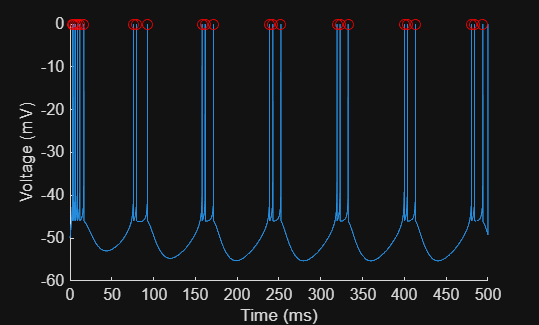

% Εύρεση κορυφών
timevec = (0:length(memvolt)-1)*params.dt;

[~,spikelocs] = findpeaks(memvolt);


figure, hold on
plot(timevec,memvolt)
plot(timevec(spikelocs),memvolt(spikelocs),'ro')

xlabel('Time (ms)')
ylabel('Voltage (mV)')
xticks(0:50:500)

% Μελέτη συμπεριφοράς του νευρώνα σε διαρκώς αυξανόμενο ρεύμα
inputs = linspace(10,600,20);
sps = zeros(size(inputs));

for ini=1:length(inputs)
    
    params.input = inputs(ini);
    
    memvolt = simulateAdEx(params); 
    
    [~,spikelocs] = findpeaks(memvolt,'MinPeakHeight', -20);
    
    %Μετατροπή σε spikes per seconds
    sps(ini) = numel(spikelocs) / (params.simDur/1000);

end

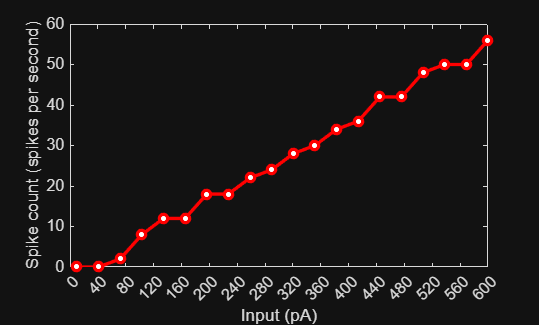

figure
plot(inputs,sps,'-ro','markerFaceColor','w','linew',2 ,'markersize',5);

xticks(0:40:600)
xlabel('Input (pA)')
ylabel('Spike count (spikes per second)')

    Το τελευταιο διάγραμμα μας δείχνει πως αυξάνονται τα spikes για ρεύμα που αυξάνεται κατα 20 pA τη φορά μέχρι να φτάσει τα 600 pA. Στη καμπύλη παρατηρείται πως 2 τιμές ίδιου ρεύματος εμφανίζουν ίδιο αριθμό από spikes. Αυτό συμβαίνει όταν η αύξηση του ρεύματος δεν είναι επαρκής για να προκληθεί νέο spike